bicycle = imread("ud810\course_images\bicycle.png");
dolphin = imread("ud810\course_images\dolphin.png");

Size of the images that you are adding need to be same. 

tiny = imread("tiny.PNG");
tiny = rgb2gray(tiny);
size(tiny)

ans =     56    56


size(dolphin)

ans =    320   500


% tiny + dolphin

the no. of color channels need not be same

tinyrgb = imread("tiny.PNG");
size(tinyrgb)

ans =     56    56     3


% if you don't give the third dimension it takes default as 1 acc to what I
% see
one = tinyrgb(1:10,1:10);
two = dolphin(1:10,1:10);
add1 = one + two

add1 = 10×10 uint8 matrix
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255


one = tinyrgb(1:10,1:10,:)

one = 10×10×3 uint8 array
one(:,:,1) =

   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   251   237   231   231   231   231   231
   255   255   255   237   245   255   255   255   255   255
   255   255   255   231   255   255   253   251   248   247
   255   255   255   231   255   255   254   252   249   248
   255   255   255   231   255   255   255   253   250   250
   255   255   255   231   255   255   255   254   252   252
   255   255   255   231   255   255   255   255   253   244


one(:,:,2) =

   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   231   150   118   118   118   118   118
   255   255   255   150   198   255   255   255   255   255
   255   255   255   118   25

% looks like it adds the same matrix to all three dimensions
add2 = one + two 

add2 = 10×10×3 uint8 array
add2(:,:,1) =

   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255


add2(:,:,2) =

   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   216   180   198   213   203   200
   255   255   255   248   255   255   255   255   255   255
   255   255   255   224  

Because both are uint8 the sum matrix has been converted to uint8 and therefore the values which went out of range were washed out and limited to 255

sum = bicycle + dolphin

sum = 320×500 uint8 matrix
   108   104   107   128   135   117   109   110   129   162   147   103   139   146   125   121   144   148   155   153   128   137   146   149   146   143   154   172   173   156   138   133   157   154   147   165   143   136   158   166   161   151   141   148   150   128   167   213   214   223
   118    73    92    86   106   101   107   110   112   109   121   134   128   120   105   111   132   134   108   126   136   141   135   147   152   151   146   141   143   150   158   161   134   128   121   153   135   132   123   128   148   171   167   154   163   176   222   224   231   248
   134    95   101    79    97   102    93   108   141   134   102   106   108    92   107   115   109   109   105   111   131   141   131   123   129   135   147   154   142   135   170   160   148   146   156   148   136   140   134   153   179   187   167   140   148   174   233   250   224   255
   105    86    97    97   100    95   117   144   143   141   142   1

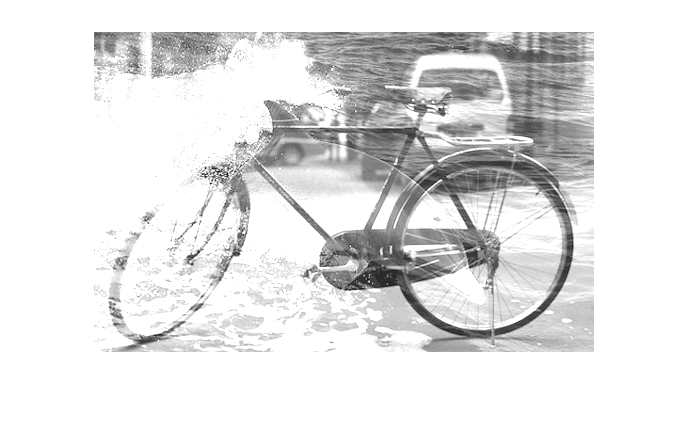

imshow(sum);

To avoid washing out affect take average

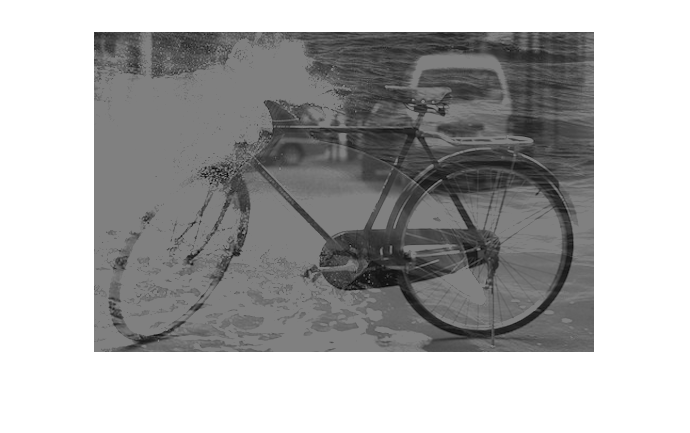

% not sum = (bicycle + dolphin)/2 because the addition already converted
% them to uint8 and washed out 

sum1 = (bicycle + dolphin)/2; 
imshow(sum1);

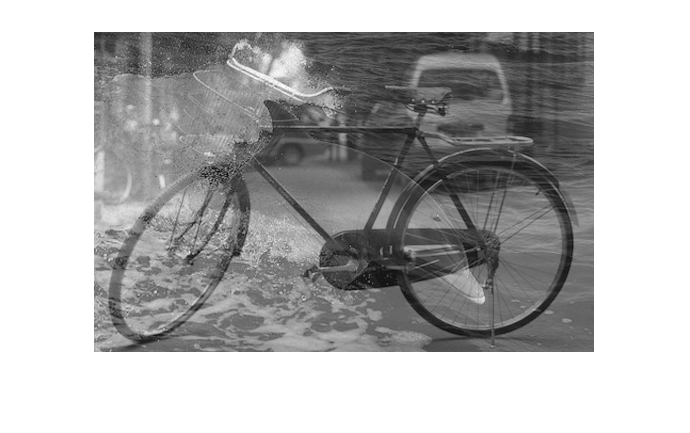

sum2 = bicycle/2 + dolphin/2; 
imshow(sum2);

Blending images : 

In order to keep the maximum intensity values the same as the one in orginal images, we need to make sure the weights add to 1 

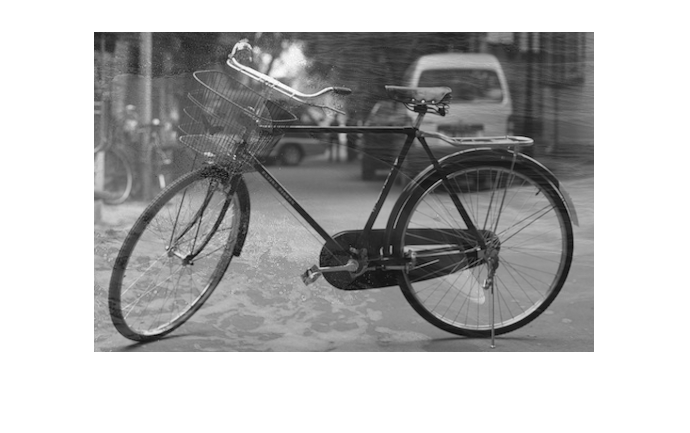

blend = 0.75* bicycle + 0.25* dolphin;
imshow(blend);

alpha = 0.25

alpha = 0.2500

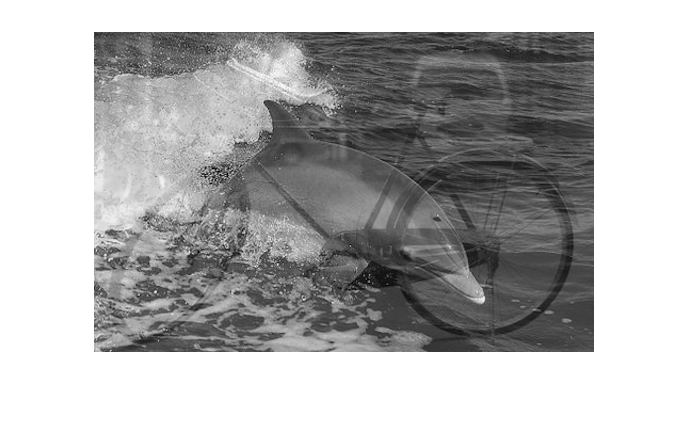

blend = alpha * bicycle + (1-alpha)*dolphin ; 
imshow (blend);